clear; close all; clc

## part a

% Given parameters
L = 0.1; % Length of the rod (m)
TL = 50; % Left boundary temperature (°C)
TR = 100; % Right boundary temperature (°C)
k = 80; % Thermal conductivity (W/mK)
q_dot = 4e5; % Heat source (W/m^3)
N = 50; % Number of nodes
dx = 2*L / (N + 1); % Grid spacing
tolerance = 1e-5; % Convergence tolerance


% Construct tridiagonal coefficient matrix and right-hand side vector
diag_values = -2 * ones(N, 1);
upper_diag_values = ones(N, 1);
lower_diag_values = ones(N, 1);
upper_diag_values(end) = 0; lower_diag_values(1) = 0;
b = -q_dot * dx^2 / k * ones(N, 1);
b(1) = b(1) - TL;
b(end) = b(end) - TR;

% Solve using Jacobi method with tridiagonal matrices
[jacobi_sol, iterations] = jacobi_method_tridiagonal(diag_values, upper_diag_values, lower_diag_values, b, tolerance, TR, TL)

jacobi_sol =    52.9027
   55.7284
   58.4773
   61.1493
   63.7444
   66.2625
   68.7039
   71.0683
   73.3558
   75.5664


iterations = 5264

## part b

% re-construct coefficient matrix A and right-hand side vector b
b = - q_dot * dx^2 / k * ones(N,1);
b(1) = b(1) - TL; b(N) = b(N) - TR;

A = -2*eye(N);
for i = 1:N-1
    A(i,i+1) = 1;
    A(i+1,i) = 1;
end


[gauss_seidel_sol, iterations]= gauss_seidel(A, b, 1000, tolerance, TR, TL)

gauss_seidel_sol =    52.8632
   55.6498
   58.3600
   60.9938
   63.5515
   66.0332
   68.4390
   70.7691
   73.0235
   75.2024


iterations = 1000

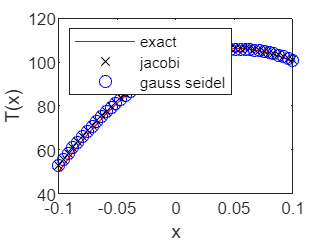

% exact solution
C1 = (TR-TL)/2/L; 
C2 = q_dot*L^2 /2/k + (TL+TR)/2;
T_exact = @(x) -q_dot./2./k.*x.^2 + C1.*x + C2;
x_values = transpose(linspace(-L, L, N));


% plotting
plot(x_values, T_exact(x_values), "r-", x_values, jacobi_sol, "kx", ...
    x_values, gauss_seidel_sol, "ob");
legend(["exact","jacobi","gauss seidel"], "Location","northwest")
ylabel("T(x)")
xlabel("x")

## functions

function [x, iterations] = jacobi_method_tridiagonal(diag_values, upper_diag_values, lower_diag_values, b, tolerance, TR, TL)
    N = length(diag_values);
    x = ones(N, 1) * (TL+TR)/2;
    % x = zeros(N, 1);
    residual_norm = inf;
    iterations = 0;
    while residual_norm > tolerance
        x_new = zeros(N, 1);

        x_new(1) = (b(1) - upper_diag_values(1)*x(2))/diag_values(1);
        for i = 2:N-1
            x_new(i) = (b(i) - upper_diag_values(i) * x(i+1) - lower_diag_values(i) * x(i-1)) / diag_values(i);
        end
        x_new(end) = (b(end) - lower_diag_values(end)*x(end-1))/diag_values(end);

        residual_norm = norm(b - tridiag_matrix_mult(diag_values, upper_diag_values, lower_diag_values, x_new), inf);
        x = x_new;
        iterations = iterations + 1;
    end
end

function result = tridiag_matrix_mult(diag_values, upper_diag_values, lower_diag_values, x)
    % Perform matrix-vector multiplication for tridiagonal matrix
    N = length(diag_values);
    result = ones(N, 1);
    
    result(1) = diag_values(1) * x(1) + upper_diag_values(1) * x(2);
    for i = 2:N-1
        result(i) = lower_diag_values(i) * x(i-1) + diag_values(i) * x(i) + upper_diag_values(i) * x(i+1);
    end
    result(N) = lower_diag_values(N) * x(N-1) + diag_values(N) * x(N);
end

function [x, iter] = gauss_seidel(A, b, max_iter, e, TR, TL)
    n = length(b);
    x = (TR + TL) / 2 *ones(n, 1);
    % x = zeros(n, 1);
    lambda = 1;
    xi_sum = 0;
    for iter = 1:max_iter
        for i = 1:n
            for j = 1:n
                if j ~= i
                    xi_sum = xi_sum + A(i,j)*x(j);
                end
            end
            x(i) = lambda*((b(i) - xi_sum)/A(i,i)) + (1 - lambda)*x(i);
            xi_sum = 0;
        end
        residual_norm = norm(A*x - b, inf);
        if residual_norm < e
            converged = true;
        else
            converged = false;
        end
        
        if iter ~= 1 && converged
            break;
        end
    end
    
end